All Days


      Source          SS        df          MS               F              Prob>F    
    __________    __________    __    ______________    ____________    ______________

    {'Groups'}    3.7398e+06     6    {[6.2330e+05]}    {[ 30.9286]}    {[2.6516e-07]}
    {'Error' }    2.8214e+05    14    {[2.0153e+04]}    {0×0 double}    {0×0 double  }
    {'Total' }    4.0219e+06    20    {0×0 double  }    {0×0 double}    {0×0 double  }



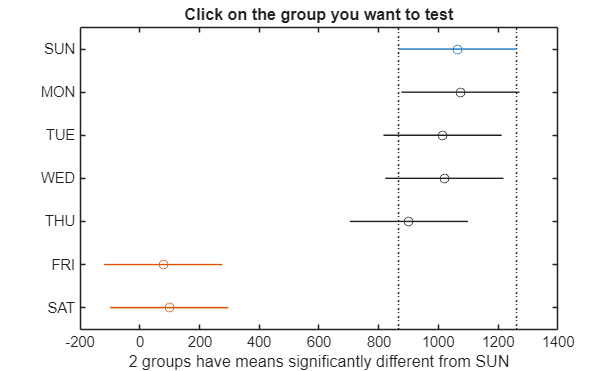

Middle of the Week


      Source          SS        df          MS               F             Prob>F   
    __________    __________    __    ______________    ____________    ____________

    {'Groups'}         56592     4    {[1.4148e+04]}    {[  0.5090]}    {[  0.7308]}
    {'Error' }    2.7798e+05    10    {[2.7798e+04]}    {0×0 double}    {0×0 double}
    {'Total' }    3.3457e+05    14    {0×0 double  }    {0×0 double}    {0×0 double}



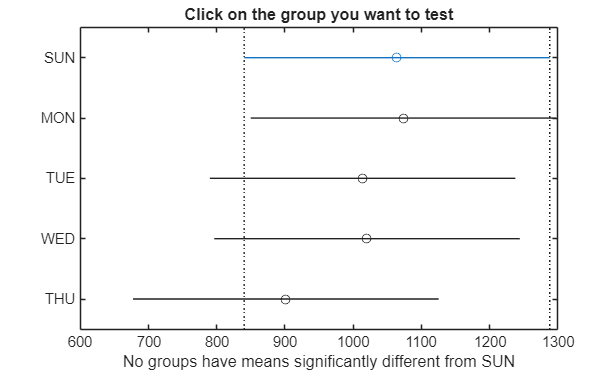

Quarter of the Year


      Source          SS        df          MS               F             Prob>F   
    __________    __________    __    ______________    ____________    ____________

    {'Groups'}    1.2631e+05     3    {[4.2103e+04]}    {[  0.7180]}    {[  0.5686]}
    {'Error' }    4.6913e+05     8    {[5.8642e+04]}    {0×0 double}    {0×0 double}
    {'Total' }    5.9544e+05    11    {0×0 double  }    {0×0 double}    {0×0 double}



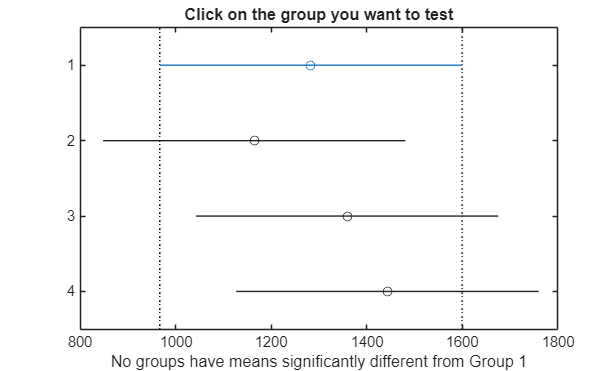

eda = EDA('temp\processed_issues.csv');
tests = eda.anovaTestForIssuesCountPerDay(2);
for i = 1:length(tests)
    figure
   t = tests{i};
   disp(t{1});
   table = cell2table(t{3}(2:end,:), 'VariableNames',t{3}(1,:));
   disp(table)
   multcompare(t{4});
   disp("====================================================================")
end